# Momentum theory for coaxial rotors

Derivations based upon:  

Leishman, J. Gordon, and Monica Syal. "Figure of merit definition for coaxial rotors." *Journal of the American Helicopter Society* 53.3 (2008): 290-300.

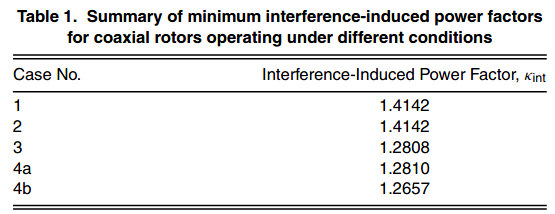

# Coaxial rotor model: Equal upper and lower inflows

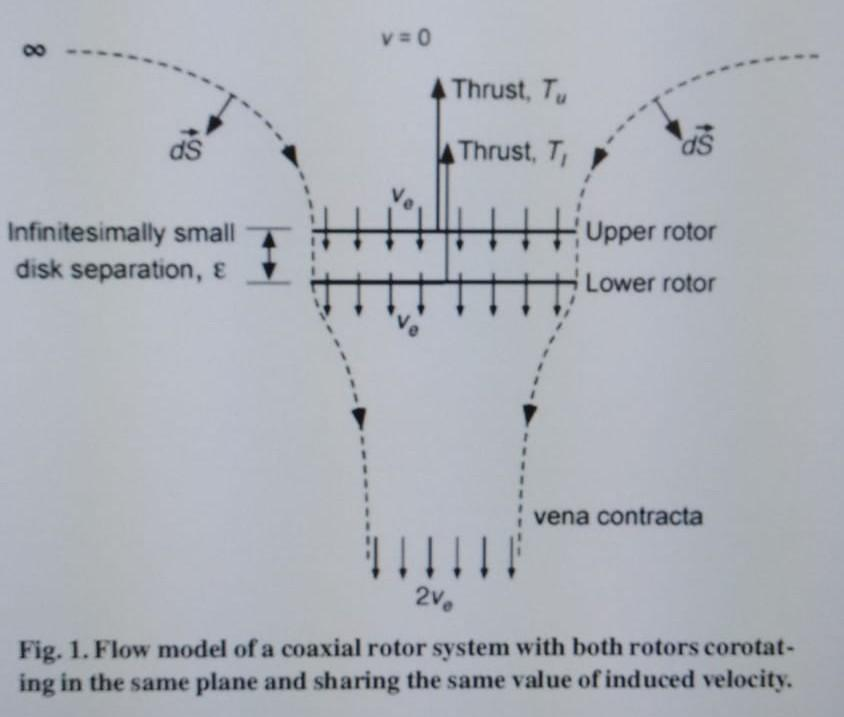

Source: Leishman, J. Gordon, and Monica Syal. "Figure of merit definition for coaxial rotors." *Journal of the American Helicopter Society* 53.3 (2008): 290-300.

This condition is only possible at a Thrust-sharing ratio of 1. Because in MT, equal induced velocity results in equal Thrust. 

This condition produces a kint = coaxEqual_P / coaxIsola_P = 1.4142

# Coaxial rotor model: Isolated upper and lower inflows

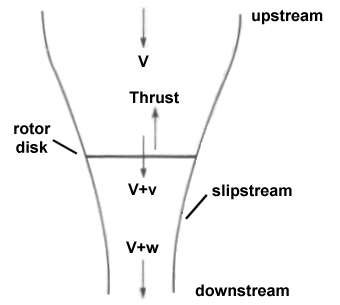

## Min Power as function of Thrust

clear all
close all
format compact

syms rho A T_0 lambda
syms T_1 T_2
assume(A>0);
assume(rho>0);
assume(T_0>0);
assume(T_1>0);
assume(T_2>0);

P_1 = sqrt(T_1^3/(2*rho*A));
P_2 = sqrt(T_2^3/(2*rho*A));
P_ind = simplify( P_1 + P_2 )

$$P\_ind = \frac{\sqrt{2}\,\left({T_{1}}^{3/2}+{T_{2}}^{3/2}\right)}{2\,\sqrt{A}\,\sqrt{\rho }}$$


% Constraint
f = T_0 - T_1 - T_2;

x = [T_1; T_2];
H = P_ind + lambda*f

$$H = \frac{\sqrt{2}\,\left({T_{1}}^{3/2}+{T_{2}}^{3/2}\right)}{2\,\sqrt{A}\,\sqrt{\rho }}-\lambda \,\left(T_{1}-T_{0}+T_{2}\right)$$

% Hx = Lx + dfdx*lambda
Hx = jacobian(H, x);
Hx = simplify(Hx);
Hx = transpose(Hx)

$$Hx = \left(\begin{array}{c} \frac{3\,\sqrt{2}\,\sqrt{T_{1}}}{4\,\sqrt{A}\,\sqrt{\rho }}-\lambda \\ \frac{3\,\sqrt{2}\,\sqrt{T_{2}}}{4\,\sqrt{A}\,\sqrt{\rho }}-\lambda \end{array}\right)$$

% Hlambda = f;
% Hlambda = jacobian(H, lambda);
% Hlambda = simplify(Hlambda);

[solx, params, conditions] = solve(Hx(1) == Hx(2), T_1, 'ReturnConditions', true)

$$solx = T_{2}$$

params =
Empty sym: 1-by-0


$$conditions = \mathrm{TRUE}$$

## Min Power as function of Omega

clear all
close all

syms k_T omega_1 omega_2 rho A T_0 lambda c_1 c_2
assume(A>0);
assume(rho>0);
assume(T_0>0);
assume(omega_1>0);
assume(omega_2>0);
assume(c_1>0);
assume(c_2>0);

% T_1 = k_T * omega_1^2;
% T_2 = k_T * omega_2^2;
% P_1 = sqrt(T_1^3/(2*rho*A));
% P_2 = sqrt(T_2^3/(2*rho*A));
P_1 = c_1 * sqrt(omega_1^6);    % c_1 = sqrt(k_T^3/(2*rho*A))
P_2 = c_1 * sqrt(omega_2^6);    % c_1 = sqrt(k_T^3/(2*rho*A))
P_ind = simplify( P_1 + P_2 )

$$P\_ind = c_{1}\,\left({\omega_{1}}^{3}+{\omega_{2}}^{3}\right)$$


% Constraint
%f = T_0/k_T - omega_1^2 - omega_2^2;
f = c_2 - omega_1^2 - omega_2^2;    % c_2 = T_0/k_T

x = [omega_1; omega_2];
H = P_ind + lambda*f

$$H = c_{1}\,\left({\omega_{1}}^{3}+{\omega_{2}}^{3}\right)-\lambda \,\left({\omega_{1}}^{2}+{\omega_{2}}^{2}-c_{2}\right)$$

% Hx = Lx + dfdx*lambda
Hx = jacobian(H, x);
Hx = simplify(Hx);
Hx = transpose(Hx)

$$Hx = \left(\begin{array}{c} 3\,c_{1}\,{\omega_{1}}^{2}-2\,\lambda \,\omega_{1}\\ 3\,c_{1}\,{\omega_{2}}^{2}-2\,\lambda \,\omega_{2} \end{array}\right)$$

% Hlambda = f;
% Hlambda = jacobian(H, lambda);
% Hlambda = simplify(Hlambda);

% Solution is omega_1 = omega_2 = sqrt(c_2/2)
[solx, params, conditions] = solve(Hx(1) == 0, omega_1, 'ReturnConditions', true)

$$solx = \frac{2\,\lambda }{3\,c_{1}}$$

params =
Empty sym: 1-by-0


$$conditions = 0<\lambda$$

[solx, params, conditions] = solve(Hx(2) == 0, omega_2, 'ReturnConditions', true)

$$solx = \frac{2\,\lambda }{3\,c_{1}}$$

params =
Empty sym: 1-by-0


$$conditions = 0<\lambda$$

# Coaxial rotor model: Lower inflow dependence on upper rotor

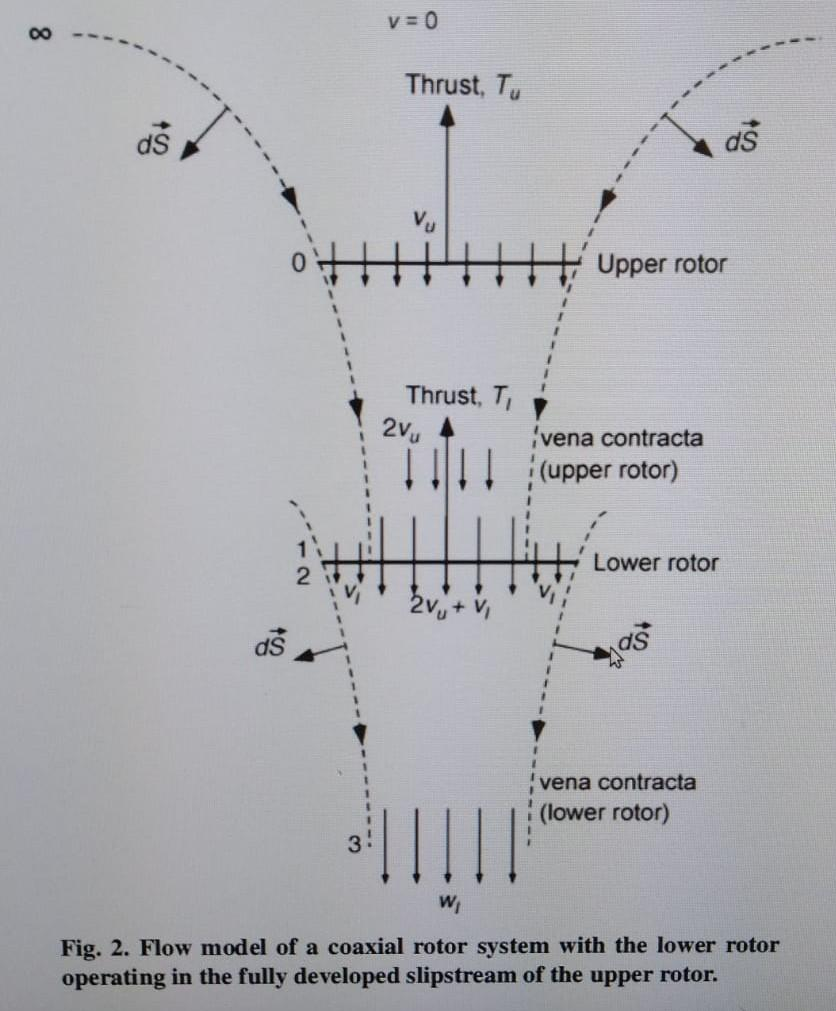 

Source: Leishman, J. Gordon, and Monica Syal. "Figure of merit definition for coaxial rotors." *Journal of the American Helicopter Society* 53.3 (2008): 290-300.

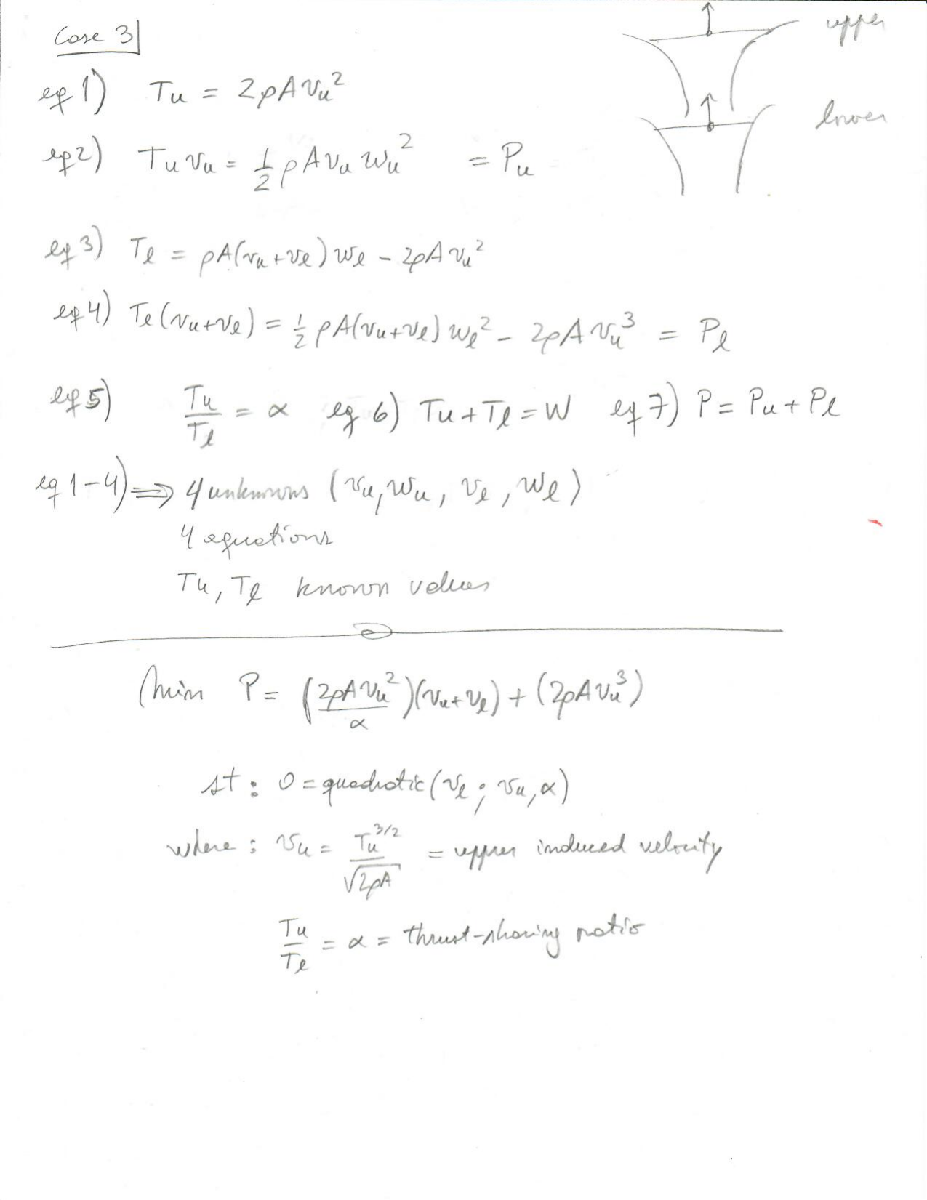

 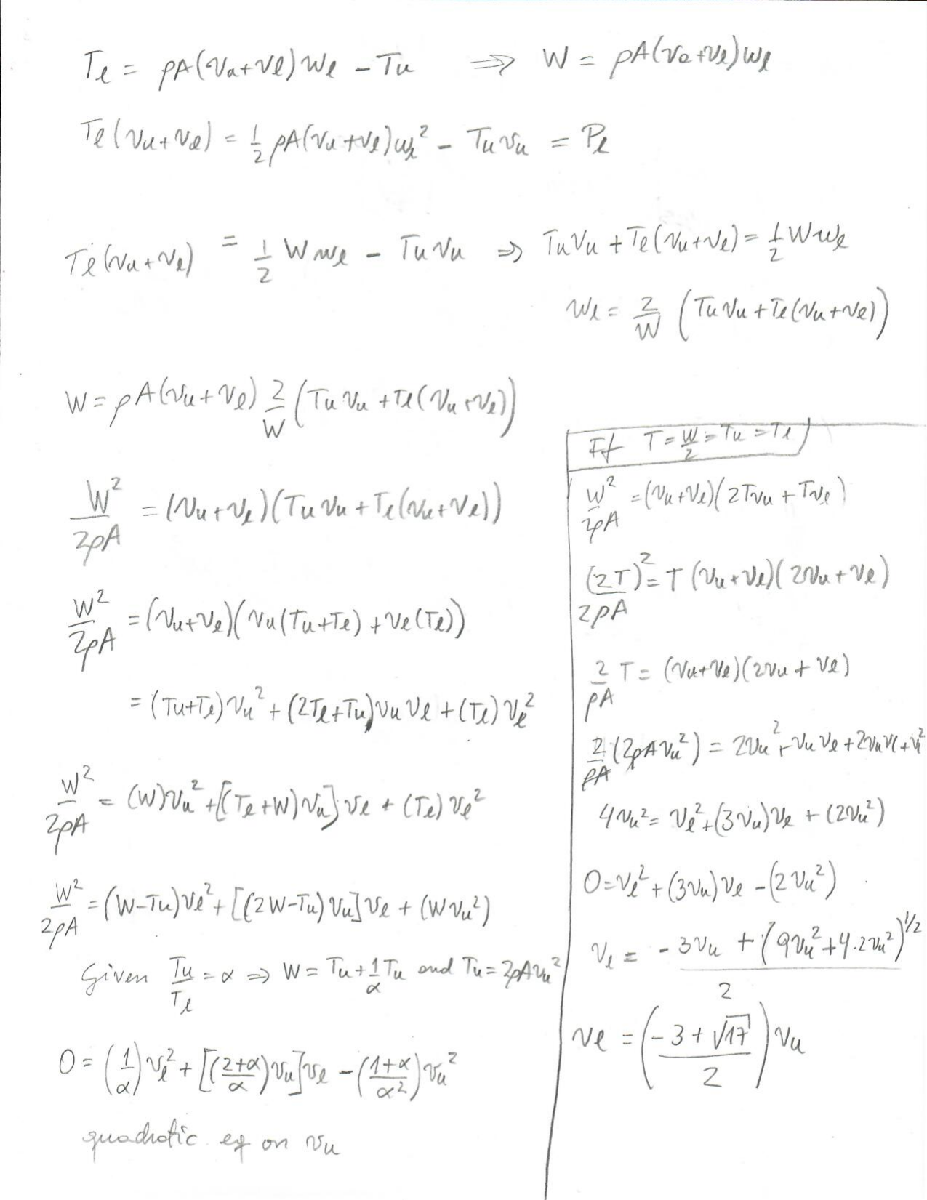

clear all
close all

syms rho A W lambda alpha
syms v_u v_l w_l
assume(v_u>0);
assume(v_l>0);
assume(w_l>0);

% [solx, params, conditions] = solve(P_l == T_l*(v_u + v_l), v_l, 'ReturnConditions', true)
eq_v_l = (1/alpha)*v_l^2 + ((2+alpha)/alpha)*v_u*v_l - ((1+alpha)/(alpha^2))*v_u^2;
[solx, params, conditions] = solve(eq_v_l == 0,v_l, 'ReturnConditions', true)

$$solx = \left(\begin{array}{c} -v_{u}-\frac{\alpha \,v_{u}}{2}-\frac{\alpha \,v_{u}\,\sqrt{\frac{\alpha^{3}+4\,\alpha^{2}+8\,\alpha +4}{\alpha^{3}}}}{2}\\ \frac{\alpha \,v_{u}\,\sqrt{\frac{\alpha^{3}+4\,\alpha^{2}+8\,\alpha +4}{\alpha^{3}}}}{2}-\frac{\alpha \,v_{u}}{2}-v_{u} \end{array}\right)$$

params =
Empty sym: 1-by-0


$$conditions = \left(\begin{array}{c} v_{u}<-\frac{\alpha \,v_{u}\,\left(\sqrt{\frac{\alpha^{3}+4\,\alpha^{2}+8\,\alpha +4}{\alpha^{3}}}+1\right)}{2}\\ v_{u}<\alpha \,v_{u}\,\left(\frac{\sqrt{\frac{\alpha^{3}+4\,\alpha^{2}+8\,\alpha +4}{\alpha^{3}}}}{2}-\frac{1}{2}\right) \end{array}\right)$$

%v_l =(sqrt( alpha^2 + 4*alpha + 8 + 4/alpha ) -alpha -2 )/2
v_l = solx(2)

$$v\_l = \frac{\alpha \,v_{u}\,\sqrt{\frac{\alpha^{3}+4\,\alpha^{2}+8\,\alpha +4}{\alpha^{3}}}}{2}-\frac{\alpha \,v_{u}}{2}-v_{u}$$

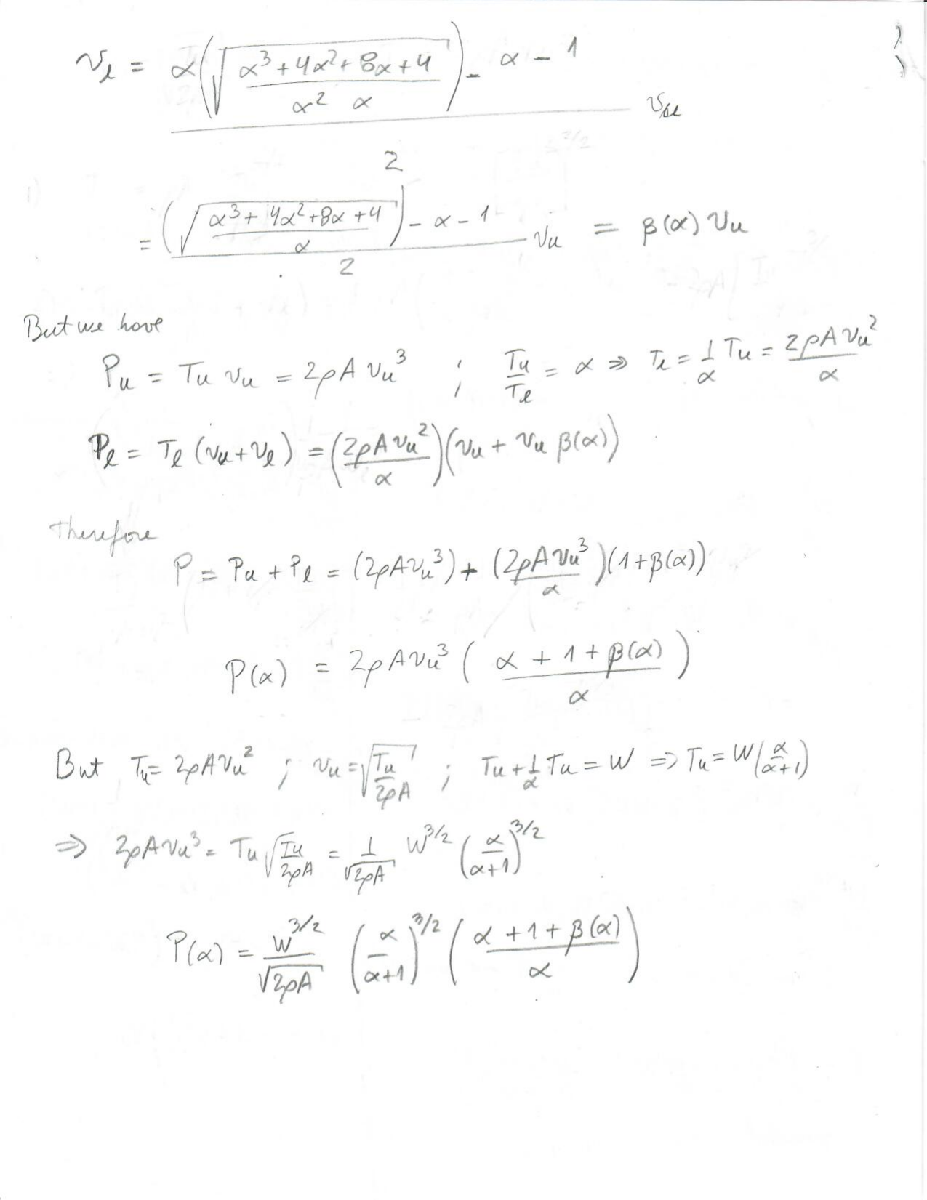

# Coaxial rotor model comparison

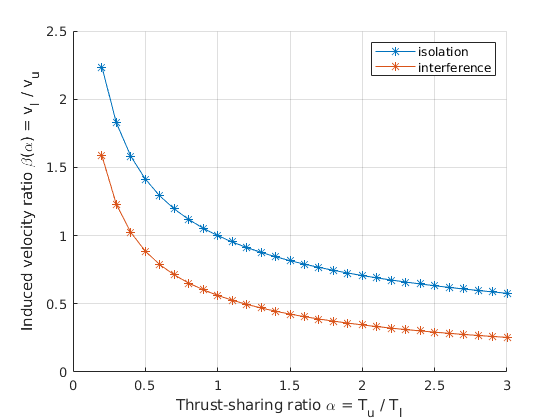

clear all
close all

alpha_arr = 0.2:0.1:3;
ns = length(alpha_arr);

coaxIsola_beta_arr = zeros(ns, 1);
coaxIsola_P_arr = zeros(ns, 1);
coaxInter_beta_arr = zeros(ns, 1);
coaxInter_P_arr = zeros(ns, 1);
for i=1:ns
    alpha = alpha_arr(i);
    
    % T_u = W*((alpha)/(alpha+1))
    % Pind = Tu*v_u = ( W*((alpha)/(alpha+1)) )*( (T_u/(2*rho*A))^0.5 )
    % Pind = ( W*normf )*( (W*((alpha)/(alpha+1))/(2*rho*A))^0.5 )
    % Pind = W^(3/2) * ((2*rhp*A)^-0.5) * ( (alpha)/(alpha+1) )^(3/2)
    normf = ( (alpha)/(alpha+1) )^(3/2);    
    
    % isolation
    beta = sqrt(1/alpha);               % alpha = T_u / T_l = v_u^2 / v_l^2
    coaxIsola_beta_arr(i) = beta;       % beta = sqrt(1/alpha)    
    Pind = (1 + beta^3);                % Pind = T_u*v_u*fnct(beta)    
    coaxIsola_P_arr(i) = normf * Pind;  % Normalize to same total weight
    
    % Interference
    beta = (sqrt( alpha^2 + 4*alpha + 8 + 4/alpha ) -alpha -2 )/2;
    coaxInter_beta_arr(i) = beta;
    Pind = (alpha + 1 + beta)/(alpha);  % Pind = T_u*v_u*fnct(beta)
    coaxInter_P_arr(i) = normf * Pind;  % Normalize to same total weight
end

figure;
hold on;
grid on;
plot(alpha_arr, coaxIsola_beta_arr, '-*')
plot(alpha_arr, coaxInter_beta_arr, '-*')
xlabel('Thrust-sharing ratio \alpha = T_u / T_l')
ylabel('Induced velocity ratio \beta(\alpha) = v_l / v_u')
legend('isolation', 'interference')

% Check if alpha=1 gives us back the result on Leishman's paper 
% for isolation and equal thrust: v_l = 1.0000*v_u
coaxIsola_beta_arr(find(alpha_arr==1))

ans = 1

% for interference and equal thrust: v_l = 0.5616*v_u
coaxInter_beta_arr(find(alpha_arr==1))

ans = 0.5616

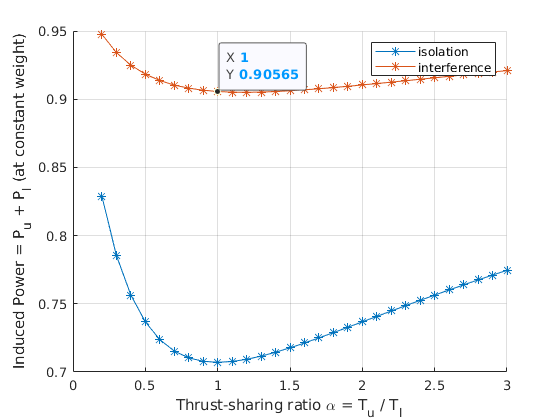

figure;
hold on;
grid on;
plot(alpha_arr, coaxIsola_P_arr, '-*')
plot(alpha_arr, coaxInter_P_arr, '-*')
xlabel('Thrust-sharing ratio \alpha = T_u / T_l')
ylabel('Induced Power = P_u + P_l (at constant weight)')
legend('isolation', 'interference')

% Check if alpha=1 gives us back the result on Leishman's paper 
% for isolation and equal torque: P_u = P_l, v_l = 1.0000*v_u and alpha = 1.0000
alpha = 1.0000;
beta = sqrt( 1/alpha )

beta = 1

coaxIsola_P = (1 + beta)

coaxIsola_P = 2

% for interference and equal torque: P_u = P_l, v_l = 0.4375*v_u and alpha = 1.4375
alpha = 1.4375;
beta = (sqrt( alpha^2 + 4*alpha + 8 + 4/alpha ) -alpha -2 )/2

beta = 0.4376

coaxInter_P = (alpha+1+beta)/(alpha)

coaxInter_P = 2.0001

% Reproduce kint
alpha = 1.0000;
beta = sqrt( 1/alpha );
coaxIsola_P = (1 + beta);

alpha = 1.0000;
beta = (sqrt( alpha^2 + 4*alpha + 8 + 4/alpha ) -alpha -2 )/2;
coaxInter_P = (alpha+1+beta)/(alpha);
kint = coaxInter_P / coaxIsola_P

kint = 1.2808